# **Lab 7. Hammerstein and Wiener models**

Through this lab we will assess the principles of non-linear identification using Hammerstein and Wiener models.

## 1. Defining a proper input signal

The firts thing to do is to decide which kind of input signal we need to use in order to properly identify the behaviour of the non-linear system. When we discussed about the identification of linear systems we always used random signals, but in this case we have to be more careful because with a random input it is possible to describe well the transient of the non-linear system, but it is not possible to describe the steady state. This phenomena is due to the fact that a random signal has an important variability over time, meaning that the non-linear system does not have enough time to reach steady state as the input suddenly changes drastically.

clc, clear all, close all

### 1.1 APRBS signals

We consider a class of signals known as Amplitude-modulated Pseudo Random Binary Signals (APRBS), which are signals that are able to change their amplitudes and their frequencies in order to find a satisfying trade-off between transient and steady state.

In order to declare an APRBS signal we write a function that will take as an input the length (number of samples) of the signal, the minimum and the maximum hold time and the minimum and the maximum amplitude. The idea is to create a signal that keeps a certain level of amplitude for a certain time interval. If we choose accordingly the amount of amplitude levels and the hold time, we wil be able to explore the behaviour of the non-linear system properly.

function u = aprbs(N,Tmin,Tmax,Vmin,Vmax)
    
    % Initialization
    L = round(Tmin + (Tmax-Tmin)*rand(1));
    u = (Vmin + (Vmax-Vmin)*rand(1))*ones(1,L);
    i = L;

    % APRBS signal
    while(i<N)
        L = round(Tmin +(Tmax-Tmin)*rand(1));
        if ((i+L) <= N)
            q=(Vmin + (Vmax-Vmin)*rand(1))*ones(1,L);
        else
            q=(Vmin + (Vmax-Vmin)*rand(1))*ones(1,N-i);
        end
        u = [u,q];
        i = i+L;
    end
end

Let's start by defining two APRBS signals. We want the first one to be quicker, in order to focus more on the transient of the non-linear system, and the second one to be slower, in order to focus more on the steady state of the non-linear system.

% Quick APRBS signal
u1 = aprbs(500,1, 5,-4,4);

% Slow APRBS signal
u2 = aprbs(500,5,25,-4,4);

### 1.2. Comparing input signals

In order to understand the differences between the two input signals, let's plot them.

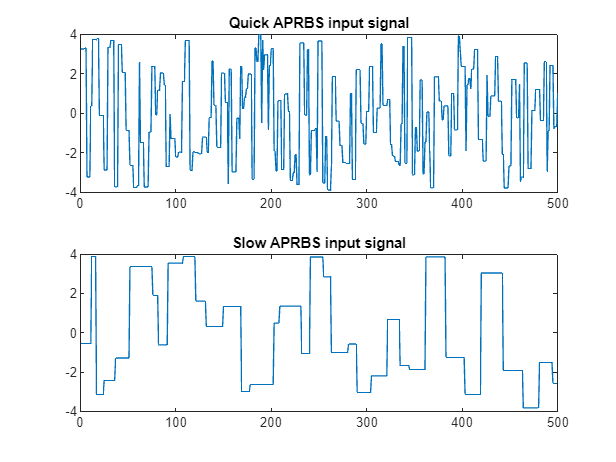

% Comparing APRBS signals
figure(1),
subplot(2,1,1), plot(u1), title("Quick APRBS input signal"),
subplot(2,1,2), plot(u2), title("Slow APRBS input signal");

As we can see the signals do not switch immediately from one amplitude level to another, and this is partially due to the fact that MATLAB performs a sort of interpolation in the plots. In order to achieve a better visualization, we use the command `stairs`.

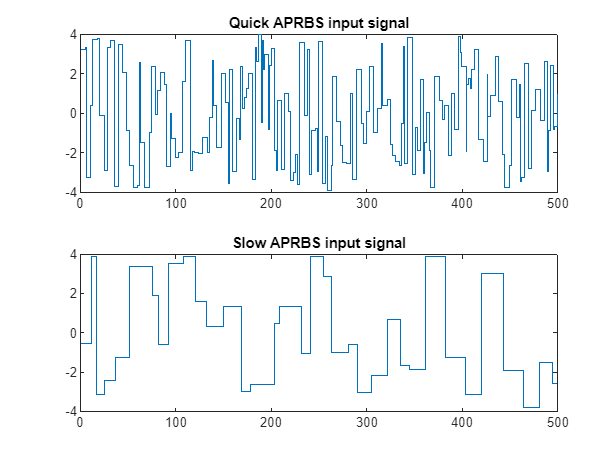

% Comparing APRBS signals
figure(2),
subplot(2,1,1), stairs(u1), title("Quick APRBS input signal"),
subplot(2,1,2), stairs(u2), title("Slow APRBS input signal");

As we can see the first APRBS input signal is very nervous and changes its amplitude levels very quickly, while the second APRBS input signal is much slower. What we will see is that if we apply the first input, the system will most likely not reach steady state because of the high variability of the input over time, while if we apply the second input, the system will probably reach steady state but we will not be able to describe appropriately the transient of the system.

## 2. Implementing the non-linear system

In order to evaluate the effects of the input signals on the non-linear system, we need to define it.

### 2.1. Defining the non-linear function

The non-linear function that expresses the output of the system at each time instant is based on the values of the input and of the output at the previous time instant. We can see that it can be split in a non-linear static part, which has no memory, and in a linear dynamic part, which instead has memory because it depends on the previous value of the output of the system.

function [y] = f(y1,u1)
    
    % Output of the system
    y = 0.1*atan(u1) + 0.9*y1;

end

Since this system does not depend from the error, it is a NARX system.

### 2.2. Simulating the non-linear system

Once we declared our function, we can simulate the behaviour of the system and compute its output given the previous inputs.

% Output given quicker input
y1 = zeros(1,500);
for t=1:499
    y1(t+1) = f(y1(t),u1(t));
end

% Output given slower input
y2 = zeros(1,500);
for t=1:499
    y2(t+1) = f(y2(t),u2(t));
end

Then we create our `iddobjects` which will be useful for the identification process.

% Datasets
data1 = iddata(y1',u1',1);
data2 = iddata(y2',u2',1);

### 2.3. Comparing outputs

Let's see what are the differences between the outputs of the system given the two input signals.

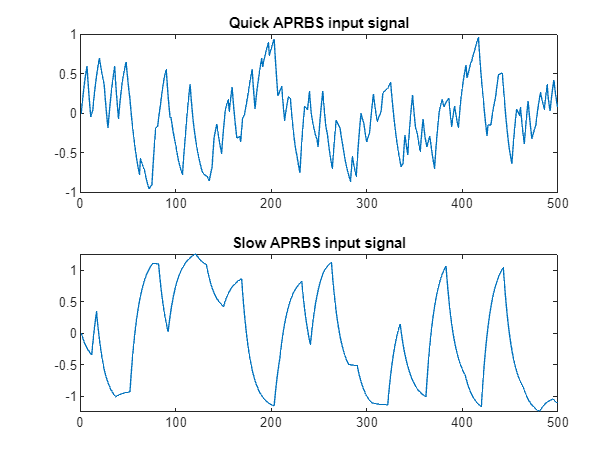

% Comparing outputs
figure(3),
subplot(2,1,1), plot(y1), title("Quick APRBS input signal"),
subplot(2,1,2), plot(y2), title("Slow APRBS input signal");

As we can see with the first input the system is not able to reach steady state, while with the second input the system is kind of reaching the steady state but it is still not there. In fact, the output increases, then tries to go to steady state, but then immediately goes to another transient phase since the input changes roughly. This means that, if we want to look at the behaviour of the non-linear system at steady state, maybe we should need an input that is slower than the ones we already considered.

## 3. Performing identification

Since the data generation mechanism is not known to us, we start our identification task by considering the simplest models. Then, the results will tell us that maybe it is the case to change the family of the model to a more complex one.

### 3.1. Splitting data

We have enough data samples to perform the split in training set and validation set. Let's consider the case of the second input signal.

% Splitting data
train = data2(1:250);
valid = data2(251:500);

As we can see we use half of the data for the training and half of the data for the validation

### 3.1. Linear identification

Let's see what happens if we try to identify the system behaviour using a linear model.

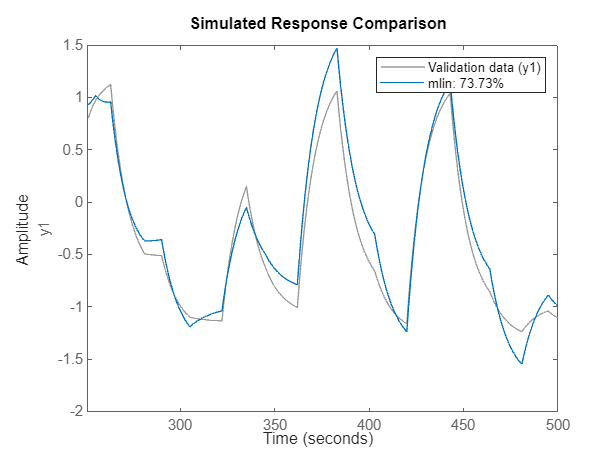

% ARX(2,2,1) model
mlin = arx(train,[2,2,1]);

% Validating model
figure(4), compare(valid,mlin);

As we can see we have actually a high fit if we think that we used a linear model. Let's perform a quick whiteness test.

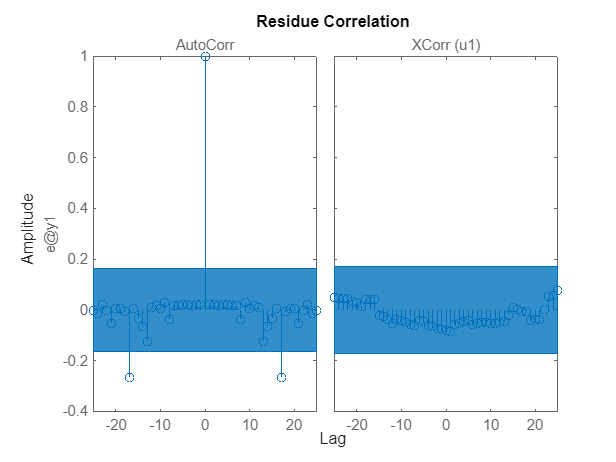

% Whiteness test
figure(5), resid(valid,mlin);

If we only looked at the autocorrelation and at the cross-correlation functions, we would have thought that this model was acceptable.

### 3.2. Non-linear identification

Let us now consider the non-linear family of Hammerstein and Wiener models. We use the command `nlhw` in order to identify our model. We need to specify the training set, the parameters of the model and some useful information about the input signal.

This is very important because the non-linear system strongly depends on the input. The more information we give about the behaviour of the imput, the better are the results obtained with the trained model. Since our input signal is a piecewise linear function, we specify this information using the `idPiecewiseLinear` argument and by specifying the minimum and maximum amplitude.

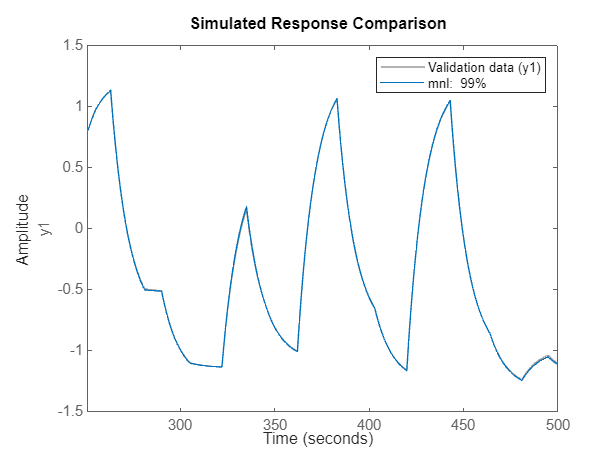

% Non-linear model
mnl = nlhw(train,[2,2,1],idPiecewiseLinear('Br',-4:0.8:4),[]);

% Validating model
figure(6), compare(valid,mnl);

As we can see the results are outstanding, with a very high value in the fit.

### 3.3. Checking breakpoints

We now look at an important property of the non-linear model which will help us understand better the quality of the fit.

% Breakpoint
bp = mnl.InputNonlinearity.BreakPoints;

The breakpoints are actually points that describe the non-linear part of the system. By plotting them, we can understand if we identified the non-linear part of the system in a good way. Let's compare the real non-linear part of the system and the breakpoints.

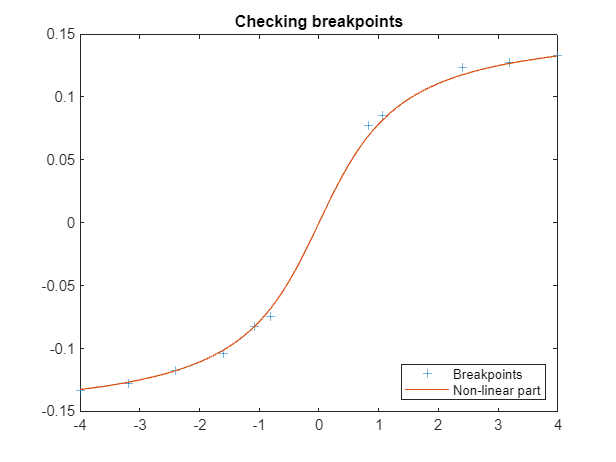

% Plotting breakpoints
figure(7), plot(bp(1,:),bp(2,:),'+',-4:0.1:4,0.1*atan(-4:0.1:4)),
legend("Breakpoints","Non-linear part","location","southeast"),
xlim([-4,4]), title("Checking breakpoints")

As we can see we identified almost perfectly the non-linear part of the system.

### 3.4. Changing the input signal

Let us now consider what happens if we use a really slow input signal. Let's define for example the following APRBS signal.

% Very slow APRBS signal
u3 = aprbs(500,10,70,-4,4);

We repeat again all the process.

% System simulation
y3 = zeros(1,500);
for t=1:499
    y3(t+1) = f(y3(t),u3(t));
end

% Dataset
data3 = iddata(y3',u3',1);

% Splitting
train3 = data3(1:250);
valid3 = data3(251:500);

Let's first evaluate the linear model.

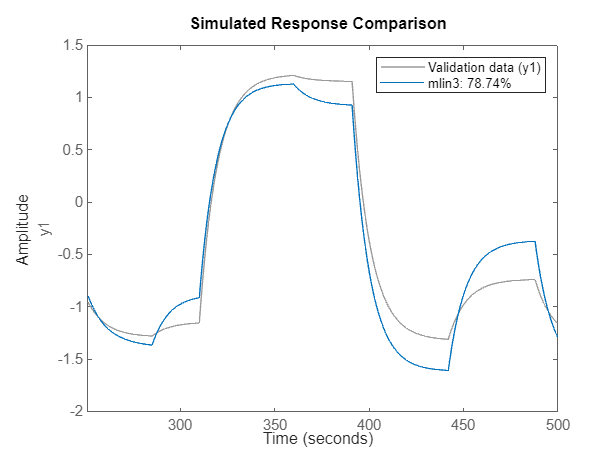

% ARX(2,2,1) model
mlin3 = arx(train3,[2,2,1]);

% Validating model
figure(8), compare(valid3,mlin3)

As we can see the fit of the model decreased a lot. Looks like there is an offset. Let's perform a quick whiteness test.

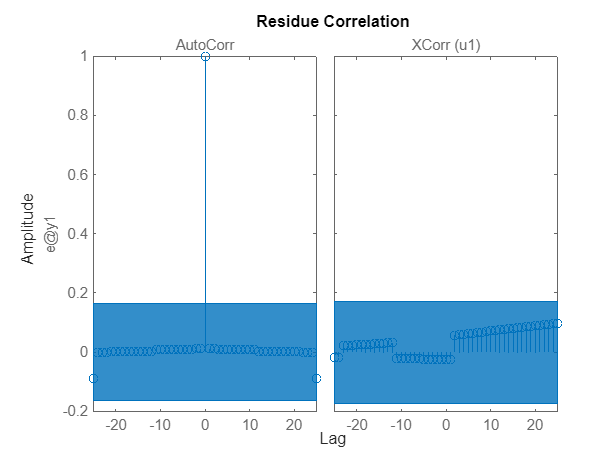

% Whiteness test
figure(9), resid(valid3,mlin3)

Results are still not that bad. Let's evaluate the non-linear model.

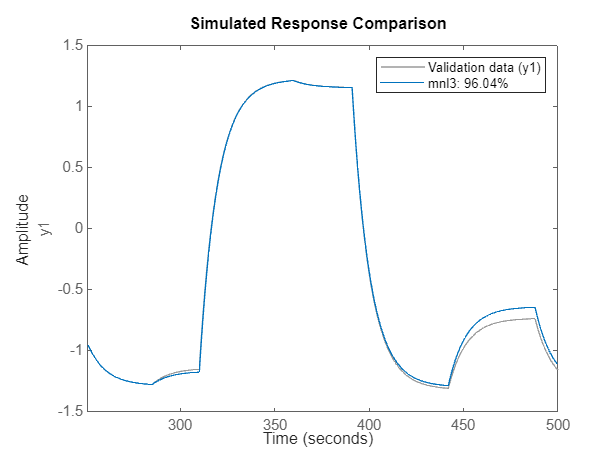

% Non-linear model
mnl3 = nlhw(train3,[2,2,1],idPiecewiseLinear('Br',-4:0.8:4),[]);

% Validating model
figure(10), compare(valid3,mnl3)

The fit is actually still good but the results have gotten worse. Let's see the breakpoints.

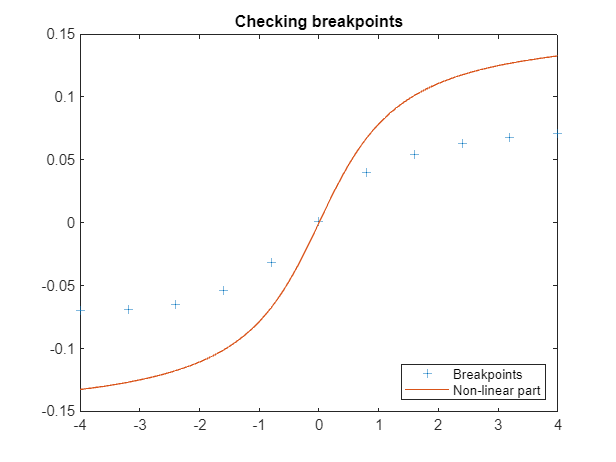

% Breakpoint
bp3 = mnl3.InputNonlinearity.BreakPoints;

% Plotting breakpoints
figure(7), plot(bp3(1,:),bp3(2,:),'+',-4:0.1:4,0.1*atan(-4:0.1:4)),
legend("Breakpoints","Non-linear part","location","southeast"),
xlim([-4,4]), title("Checking breakpoints")

Here we can understand that, even if the fit was actually high, we weren't able to identify propertly the non-linear part of the system.